**Group Members: Irtaza Tanveer (24100039) & Muhammad Hamza Khawaja (24100043)**

**TASK1 CASE1**

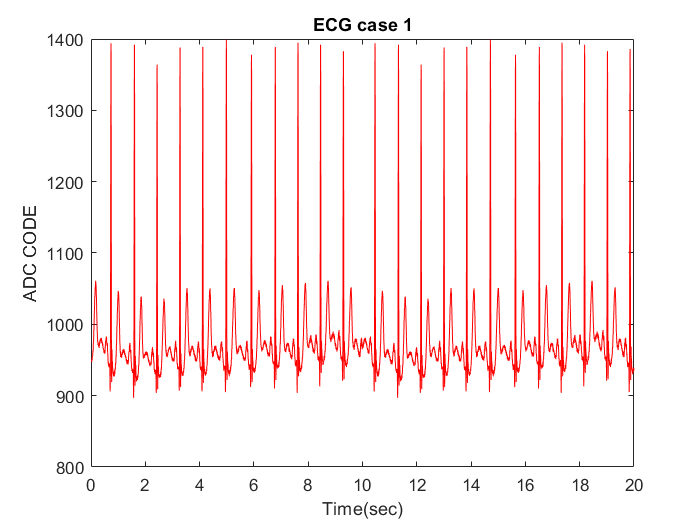

load ECG_case_1.mat
ECG1=ECG;
Fs1=Fs;
t1=0:1/360:20;   %sampling rate and fs was same
plot(t1,ECG1,'red')
hold on
ylabel('ADC CODE')
xlabel('Time(sec)')
title('ECG case 1')
hold off

#### **TASK1 CASE2**

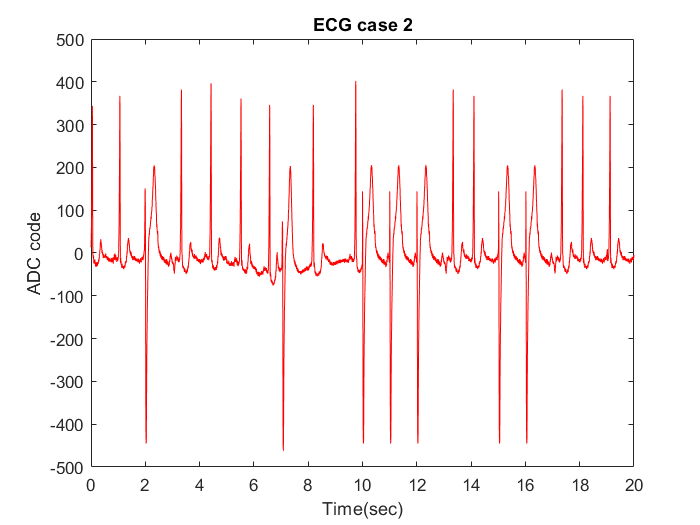

load ECG_case_2.mat
ECG2=ECG;  %%both stored as ecg but different length
Fs2=Fs;
t2=t1(1:20*Fs); % making time2same asecg2
plot(t2,ECG2,'red')
hold on
ylabel('ADC code')
xlabel('Time(sec)')
title('ECG case 2')
hold off

From looking at the graphs, ECG Case 1 does not seem to show any type of cardiac arrythmia since none of the conditions needed are being satisfiied.

ECG Case 2 does show signs of PVC due to the following features in the plot for Case 2: 

1) A large negative S-wave amplitude 

2) A T-wave with an amplictude greater than 100

3) The time interval between the S wave and the T wave being larger than 0.28s.

The three features above being repeated multiple times across the ECG plot for Case 2, which also indicates a potential case of VT.

The PVCs for ECG2 seem to be occurring at 2s, around 7s, 10s, around 11s, 12s, around 15s and 16s.

The VT for ECG2 seems to be occuring between 10s and 12s, where 3 consecutive PVCs can be seen.

#### **TASK 2**

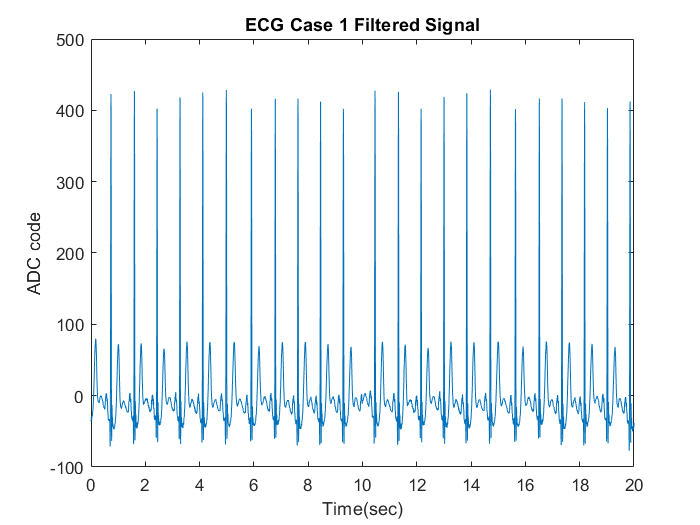

ECG1=ECG1-mean(ECG1);%% removing dc offset from ecg1

[ecg1, f1]=frft(ECG1, Fs1);

lcutoff=0.5;
df=f1(2)-f1(1);
lcutoff_idx=ceil(lcutoff/df);
ucutoff=45;
ucutoff_idx=ceil(ucutoff/df);
ecg1_filtered=ecg1;
ecg1_filtered(1:lcutoff_idx-1) = 0;
ecg1_filtered(ucutoff_idx+1:end) = 0;
[ECG1_FILTERED, t1]=invfrft(ecg1_filtered, f1, Fs1);
plot(t1, ECG1_FILTERED)
ylabel('ADC code')
xlabel('Time(sec)')
title('ECG Case 1 Filtered Signal')

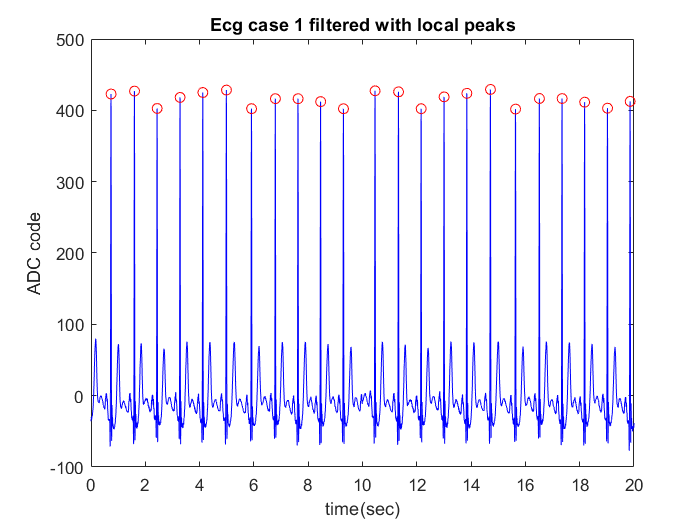


[R1Peaks,R1Locations]=findpeaks(ECG1_FILTERED,'MinPeakDistance',0.8*Fs1);
plot(t1, ECG1_FILTERED, 'blue')
hold on
plot(R1Locations/Fs1,R1Peaks,'ro')
title('Ecg case 1 filtered with local peaks')
ylabel('ADC code')
xlabel('time(sec)')
hold off


average_beat_rate_bpm=(length(R1Peaks)/20)*60

average_beat_rate_bpm = 69

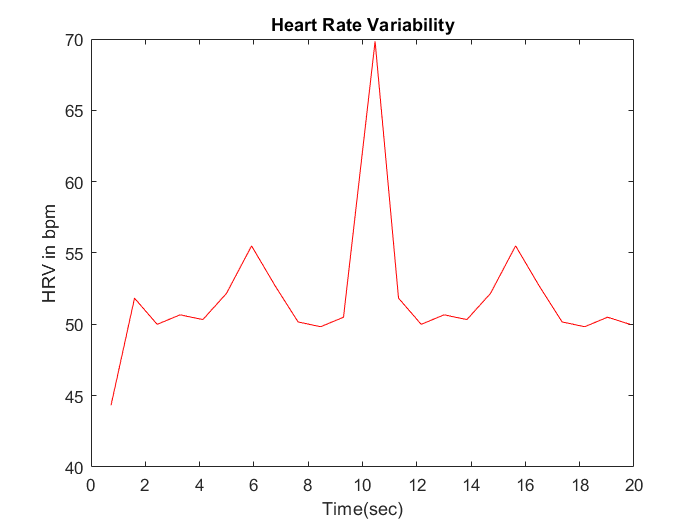


difference_vector=zeros(1,length(R1Locations)); % creating this displaced vector so can get variation in each in each step
difference_vector(2:end)=R1Locations(1:end-1);
RR_variation=R1Locations-difference_vector; %get variation that after how much samples r peak occurs
RR_variation=(RR_variation./Fs1)*60;  % conver it to beats per minute

plot(R1Locations./Fs1,RR_variation,'red')
title('Heart Rate Variability')
ylabel('HRV in bpm')
xlabel('Time(sec)')

#### **TASK 3**

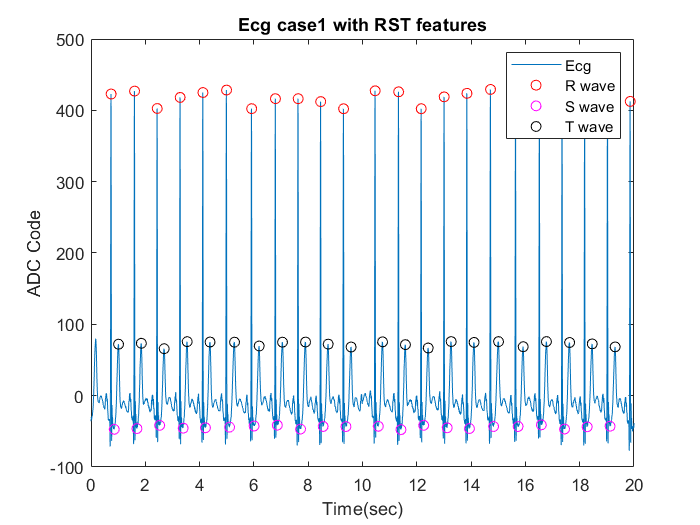

%A_idx is storage box and idx_of_A_Max are indivisual peaks found in each state 
%  A is (R, S, T) peaks name
% ecg1_filtered length is 7201
% 0.8*Fs1 is the gap b/w each rr peak
% 0.4*Fs1 is gap b/w r and s peak
% we add 12 in finding S and T peak which moves us out of whole rpeak


state_10=true;
state_11=false;
state_12=false;
R1_amp=zeros(1,length(ECG1_FILTERED));  % storage boxes for amplitude and indexes
S1_amp=zeros(1,length(ECG1_FILTERED));
R1_idx=zeros(1,length(ECG1_FILTERED));
S1_idx=zeros(1,length(ECG1_FILTERED));
T1_amp=zeros(1,length(ECG1_FILTERED));
T1_idx=zeros(1,length(ECG1_FILTERED));
Minimum_R1_amplitude_for_R1peaks=min(R1Peaks); % skips the false R peaks lower than minimum 

for i=1:0.8*Fs1:length(ECG1_FILTERED)  %0.8*Fs1 is gap between next qrs pattern and length is the total elements
    
    %% ----rpeak----
    if (i+(0.8*Fs1))>length(ECG1_FILTERED)  % saves us  on the next line of code  and helps to get out of loop      --
        break                    
    end   
    [Max_R1, idx_of_Max_R1]=max(ECG1_FILTERED(i:i+(0.8*Fs1)));  % here dont runs beyond lenght(7201) of ecg array
    if(Max_R1>=Minimum_R1_amplitude_for_R1peaks)   %% only take those above the threshold
        state_10=false;       % so next time we can reenter this once find s and t peak
        idx_of_Max_R1=i+idx_of_Max_R1;   % getting exact location correspong to ecg array
        R1_idx(idx_of_Max_R1)=idx_of_Max_R1;   %usin our storage box to keep indexes and amplitudes
        R1_amp(idx_of_Max_R1)=Max_R1;
        state_11=true;
      
    %%-----speak-------
        if(state_11==true)
            if (idx_of_Max_R1+0.4*Fs1<length(ECG1_FILTERED)) %this 12 below is the spacing between R peak and to the bottom where it ends
                [Min_S1, idx_of_Min_S1]=min(ECG1_FILTERED(idx_of_Max_R1+12:idx_of_Max_R1+0.4*Fs1)); %% find S from bottom of qrs to 0.4seconds distance
                idx_of_Min_S1=idx_of_Max_R1+12+idx_of_Min_S1; % find it corresponding to idx in ecg array
                S1_amp(idx_of_Min_S1)=Min_S1;  %% placing them in storage boxes
                S1_idx(idx_of_Min_S1)=idx_of_Min_S1;
                state_12=true; % as s located make it true to enter 3rd state
                state_11=false; % the state we enter make it false so can re enter later
                
                %----tpeak-------
                if (state_12==true)
                    if (idx_of_Max_R1+150<length(ECG1_FILTERED)) % saves us going beyond lenght of ecg in next line
                        [Max_T1, idx__of_Max_T1]=max(ECG1_FILTERED(idx_of_Max_R1+12:idx_of_Max_R1+150)); % 12=0.03*360 starts from bottom of qrs else pick R peak as T peak and 150 is spacing till T
                        idx__of_Max_T1=idx__of_Max_T1+idx_of_Max_R1+12;% get corresponding to ecgfiltered
                        T1_amp(idx__of_Max_T1)=Max_T1; % storage box
                        T1_idx(idx__of_Max_T1)=idx__of_Max_T1;
                        state_12=false; % make false to reenter it
                        state_11=false;
                    end
                end
            end
        end
    end
end


plot( t1,ECG1_FILTERED)
hold on
plot(R1_idx(R1_amp>0)./Fs1,R1_amp(R1_amp>0),'ro')
plot(S1_idx(S1_amp<0)./Fs1,S1_amp(S1_amp<0),'mo')
plot(T1_idx(T1_amp>0)./Fs1,T1_amp(T1_amp>0),'ko')
title('Ecg case1 with RST features')
ylabel('ADC Code')
xlabel('Time(sec)')
legend('Ecg','R wave', 'S wave', 'T wave')
hold off

#### **Filtering ECG2 FOR Task 4**

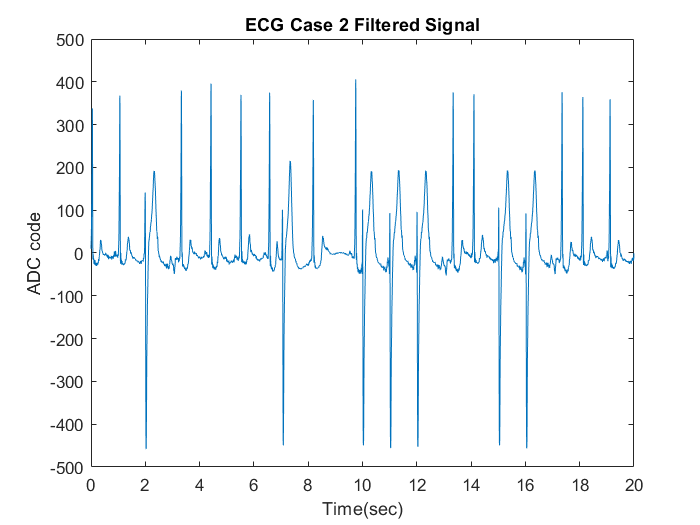

ECG2=ECG2-mean(ECG2);%% removing dc offset from ecg1

[ecg2, f2]=frft(ECG2, Fs2);

lcutoff=0.5;
df=f2(2)-f2(1);
lcutoff_idx=ceil(lcutoff/df);
ucutoff=45;
ucutoff_idx=ceil(ucutoff/df);
ecg2_filtered=ecg2;
ecg2_filtered(1:lcutoff_idx-1)=0;
ecg2_filtered(ucutoff_idx+1:end)=0;
[ECG2_FILTERED, t2]=invfrft(ecg2_filtered, f2, Fs2);
plot(t2, ECG2_FILTERED)
ylabel('ADC code')
xlabel('Time(sec)')
title('ECG Case 2 Filtered Signal')

#### Task 4 : finding R,S,T patterns

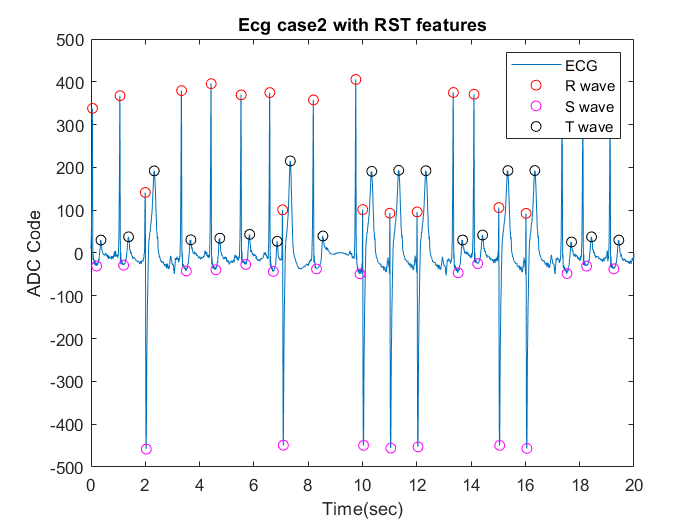

%A_idx is storage box and idx_of_A_Max are indivisual peaks found in each state 
%  A is (R, S, T) peaks name
% ecg2_filtered length is 7200
% 91 is the gap b/w samples take (as minimum gap b/w two rr peak was 0.25s)
% 0.2*Fs1 is gap b/w r and s peak(0.2 second was the minimum recorded)
% we add 12 in finding S and T peak which moves us out of whole rpeak

state_20=true;
state_21=false;
state_22=false;
R2_amp=zeros(1,length(ECG2_FILTERED));  % storage boxes for amplitude and indexes
S2_amp=zeros(1,length(ECG2_FILTERED));
R2_idx=zeros(1,length(ECG2_FILTERED));
S2_idx=zeros(1,length(ECG2_FILTERED));
T2_amp=zeros(1,length(ECG2_FILTERED));
T2_idx=zeros(1,length(ECG2_FILTERED));

for i=1:91:length(ECG2_FILTERED)  %  91 is minimum gap which occured between two qrs pattern, it is about 0.25 seconds
        if (i+91>length(ECG2_FILTERED))  % saves us  on the next line of code  and helps to get out of loop    
          break
        end
       [Max_R2 ,idx_of_Max_R2]=max(ECG2_FILTERED(i:i+91));  % here dont runs beyond lenght(7200) of ecg array
       
%% Explaining the if condition on line 182
%% [(condition1)||condition2] && [ condition3&& condition4]
% first part having "or" detect two type of Rpeaks>300 and b/w 80-150
% first type is when no pvc 2nd is when it have pvc
% 2nd part of condition is connected with & to the first part
% 2nd part check that whether it is a peak by
% checking that peak value is greater than adjacent points on both side
       
       if((Max_R2>=300) || (Max_R2>80 && Max_R2<150)) && (ECG2_FILTERED(i+idx_of_Max_R2)>ECG2_FILTERED(i+idx_of_Max_R2-19) && ECG2_FILTERED(i+idx_of_Max_R2)>ECG2_FILTERED(i+idx_of_Max_R2+18))  %% only take those above the threshold
          state_20=false;               
          idx_of_Max_R2=i+idx_of_Max_R2;   % getting exact location correspong to ecg array
          R2_idx(idx_of_Max_R2)=idx_of_Max_R2;   %usin our storage box to keep indexes and amplitudes
          R2_amp(idx_of_Max_R2)=Max_R2;
          state_21=true;
          
    % finding s peak
          if(state_21==true)
              if (idx_of_Max_R2+0.2*Fs2<length(ECG2_FILTERED)) %0.2*fs2 is probable distance b/w s and r peak %this 12 below is the spacing between R peak and to the bottom where it ends(to ignore noise)
                  [Min_S2 ,idx_of_Min_S2]=min(ECG2_FILTERED(idx_of_Max_R2:idx_of_Max_R2+0.2*Fs2)); %% find S from bottom of qrs to 0.2seconds distance
                  idx_of_Min_S2=idx_of_Max_R2+idx_of_Min_S2; % find it corresponding to idx in ecg array
                  S2_amp(idx_of_Min_S2)=Min_S2;  %% placing them in storage boxes
                  S2_idx(idx_of_Min_S2)=idx_of_Min_S2;
                  state_22=true; % as s located make it true to enter 3rd state
                  state_21=false; % the state we enter make it false so can re enter later
        
                  %finding t peak
                  if (state_22==true)   %% T peak
                      if (idx_of_Max_R2+150<length(ECG2_FILTERED)) % saves us going beyond lenght of ecg in next line
                          [Max_T2, idx_of_Max_T2]=max(ECG2_FILTERED(idx_of_Max_R2+12:idx_of_Max_R2+150)); % 12=0.03*360 starts from bottom of qrs else pick R peak as T peak and 150 is spacing till T

       % two type of S peak ,first if statement detect t peak with no pvc
                          if (Min_S2>-100) && (Max_T2<90)     %% 100 is amp of S when no pvc and T amp<90
                               idx_of_Max_T2=idx_of_Max_T2+idx_of_Max_R2+12;% get corresponding to ecgfiltered
                                T2_amp(idx_of_Max_T2)=Max_T2; % storage box
                                T2_idx(idx_of_Max_T2)=idx_of_Max_T2;
                                state_22=false; % make false to reenter it
                                state_21=false;
                                state_20=true;
                          end
             %% 2nd if detect T peak when there is pvc
                          if(Min_S2<-300) && (Max_T2>100)  %then S amplitude is -300 and t amplitude is>100
                                 idx_of_Max_T2=idx_of_Max_T2+idx_of_Max_R2+12;% get corresponding to ecgfiltered
                                 T2_amp(idx_of_Max_T2)=Max_T2; % storage box
                                 T2_idx(idx_of_Max_T2)=idx_of_Max_T2;
                                 state_22=false; % make false to reenter it
                                 state_21=false;
                                 state_20=true;
                          end
                    end
                end
            end
        end
    end
end

plot(t2,ECG2_FILTERED)
hold on
plot(R2_idx(R2_amp>0)./Fs2, R2_amp(R2_amp>0),'ro')
plot(S2_idx(S2_amp<0)./Fs2, S2_amp(S2_amp<0),'mo')
plot(T2_idx(T2_amp>0)./Fs2, T2_amp(T2_amp>0),'ko')
title('Ecg case2 with RST features')
ylabel('ADC Code')
xlabel('Time(sec)')
legend('ECG','R wave','S wave','T wave')
hold off

**TASK 5 ECG Case 1 **

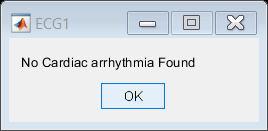

t_pvc_in_ecg1=S1_idx(S1_amp<-300); 
if(isempty(t_pvc_in_ecg1))
    msgbox('No Cardiac arrhythmia Found ', 'ECG1')
end

**TASK 5 ECG CASE 2**

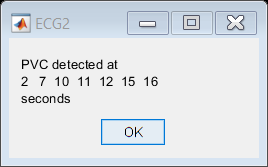

S2_idx = S2_idx(S2_amp<0);
S2_amp=S2_amp(S2_amp<0);
t_speak=zeros(1,20);
for i=1:1:20
    if(S2_amp(i) < -300)
        t_speak(i)=floor(S2_idx(i)/360);
        t_speak(i)=S2_idx(i)/360 ; 
    end
end

t_speak= floor(t_speak(t_speak>0)); %% the time stamps at which peaks occured
msgbox(["PVC detected at" num2str(t_speak(t_speak>0)) "seconds"]  , "ECG2")

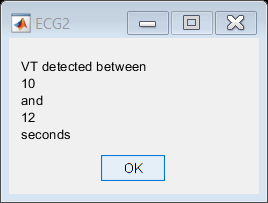


%Finding VT 
t_speak_shifted = [t_speak(2:end), 0]; %t_speak shifted one index to the right
time_difference = t_speak_shifted - t_speak; %time differences between PVCs stored here
%loop checks to see if there are 3 consecutive PVCs
%if two consecutive time difference values are 2 seconds less than each other, it is counted as two consecutive PVCs
for i=1:1:6 
    if(time_difference(i+1) - time_difference(i) < 2) 
        msgbox(["VT detected between" num2str(t_speak(time_difference(i+1))) "and" num2str(t_speak(time_difference(i))) "seconds"], "ECG2")
        break
    end
end